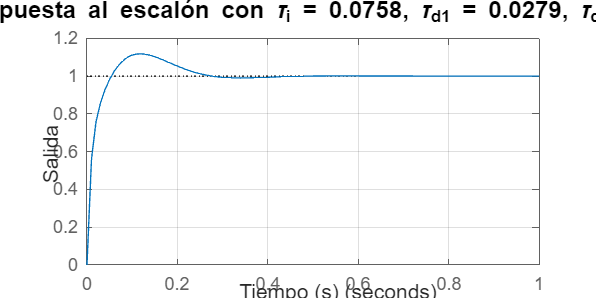

% PID_analisis_Kp.m
close all;
clear;
clc;

% Parámetros del sistema
K = 2652.28;
p = 64.986;
Kp = 1.3106;
tau_i = 0.0758;
tau_d1 = 0.0279;
tau_d2 = 0.0005;
tau_d = tau_d1 + tau_d2;
t = 0:0.01:1;

% Figura 1: respuesta al escalón
fig1 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 10]);
hold on;
    
% Numerador del PID
num_PID = K*Kp*tau_d1 * [1, 1/tau_d1, 1/(tau_d1*tau_i)];

% Denominador: suma de s^2*(s+p) y controlador
den_planta = conv([1 0 0], [1 p]);
den_control = K*Kp*tau_d * [1, 1/tau_d, 1/(tau_d*tau_i)];

% Igualar tamaños
n1 = length(den_planta);
n2 = length(den_control);
if n1 > n2
    den_control = [zeros(1, n1 - n2), den_control];
else
    den_planta = [zeros(1, n2 - n1), den_planta];
end
den_PID = den_planta + den_control;

% Sistema en lazo cerrado
sys = tf(num_PID, den_PID);
step(sys, t);

% Métricas del transitorio
[y, t_out] = step(sys, t);
info = stepinfo(y, t_out, 'SettlingTimeThreshold', 0.02);


% Estética gráfica 1
title(['Respuesta al escalón con \tau_i = ' num2str(tau_i) ', \tau_{d1} = ' num2str(tau_d1) ', \tau_{d2} = ' num2str(tau_d2)], 'FontSize', 16);
xlabel('Tiempo (s)', 'FontSize', 14);
ylabel('Salida', 'FontSize', 14);
grid on;
set(gca, 'FontSize', 12);